# **Using MATLAB to realise clustering algorithms**

**黄骁 Huang Xiao (A0244823E)                                                                                        **

- 任务：

- 考虑概率方法之后发现聚类效果超出预期，对于不同数据集进行试验

- 之前的方法是否和kmeans相同

data1og = randn(100,1); 
data2og = randn(100,1);
data3og = randn(100,1);


 
% Mission 1 generate two normally distributed datasets of N(1,0) and N(0.5,1)
fprintf('hello world');

hello world


sigma=0.7

sigma = 0.7000

data1 = sigma*data1og; 
data2 = sigma*data2og+0.5;
data3=sigma*data3og-0.5

data3 =    -0.2671
   -0.4015
    0.6045
   -0.4373
   -0.9711
    0.1523
   -0.7505
   -0.3585
    0.1134
    0.0656


cluster=[data1;data2;data3];

## Determine the number of clusters

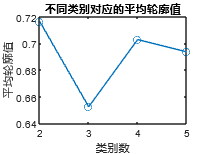

silh_method(cluster);

 
%initialization of the result sets
DIYc1=[];
DIYc2=[];
DIYc3=[];
DIYc4=[];
DIYc5=[];
DIYc6=[];
kmeansc1=[];
kmeansc2=[];
h1=[];
h2=[];

% doing probability method for 3 datasets
% [m,~]=size(cluster);
% p=rand([300,1]);
% m1=[];
% m2=[];
% m3=[];
% for i=1:300
%     if p(i)<1/3
%         m1(end+1)=1;
%         m2(end+1)=0;
%         m3(end+1)=0;
%     
%     elseif p(i)>2/3
%         m1(end+1)=0;
%         m2(end+1)=0;
%         m3(end+1)=1;
%     
%     else
%         m1(end+1)=0;
%         m2(end+1)=1;
%         m3(end+1)=0;
%     end
% 
% 
% end
% 
% result1=0;
% result2=0;
% result3=0;
% for i=1:100
%     result1=result1+m1(i)*cluster(i);
%     result2=result2+m2(i)*cluster(i);
%     result3=result3+m3(i)*cluster(i);
% end
% 
% % mu1=result1/sum(m1)
% % mu2=result2/sum(m2)
% % mu3=result3/sum(m3)
% mu1=0
% mu2=0.5
% mu3=-0.5
% %所以0,1的标记法不可以使用
centers=initialization(cluster,3)

centers =     0.4133
   -2.1534
    2.3823


mu1=centers(1)

mu1 = 0.4133

mu2=centers(2)

mu2 = -2.1534

mu2=centers(3)

mu2 = 2.3823

result=[];
a=[];
b=[];
c=[];
for i=1:50
    iter=1;
     while iter<1000
        
        PZAset=[];
        PZBset=[];
        PZCset=[];
        
    
        for i=1:m
    
            PZA=(exp(-(cluster(i)-mu1)^2/(2*sigma^2)))/((exp(-(cluster(i)-mu1)^2/(2*sigma^2)))+exp(-(cluster(i)-mu2)^2/(2*sigma^2))+exp(-(cluster(i)-mu3)^2/(2*sigma^2)));
            PZAset(end+1)=PZA;
            
            PZB=(exp(-(cluster(i)-mu2)^2/(2*sigma^2)))/((exp(-(cluster(i)-mu1)^2/(2*sigma^2)))+exp(-(cluster(i)-mu2)^2/(2*sigma^2))+exp(-(cluster(i)-mu3)^2/(2*sigma^2)));
            PZBset(end+1)=PZB;
    
            PZC=(exp(-(cluster(i)-mu3)^2/(2*sigma^2)))/((exp(-(cluster(i)-mu1)^2/(2*sigma^2)))+exp(-(cluster(i)-mu2)^2/(2*sigma^2))+exp(-(cluster(i)-mu3)^2/(2*sigma^2)));
            PZCset(end+1)=PZC;
    
    
        end      
        iter=iter+1;
        result1=0;
        result2=0;
        result3=0;
        
        for j=1:m
            result1=result1+PZAset(j)*cluster(j);
            result2=result2+PZBset(j)*cluster(j);
            result3=result3+PZCset(j)*cluster(j);
        end
        mu1=result1/sum(PZAset);
        mu2=result2/sum(PZBset);
        mu3=result3/sum(PZCset);
     end
     a(end+1)=mu1;
     b(end+1)=mu2;
     c(end+1)=mu3;


end
result=[a' b' c']

result =     0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
    0.1016    0.4408   -0.4923
